# **TAP 1**

**Integrantes:**

- Jeffrey Antonio Monja Castro

- Angello Soldi

- Juan Carlos Paredes

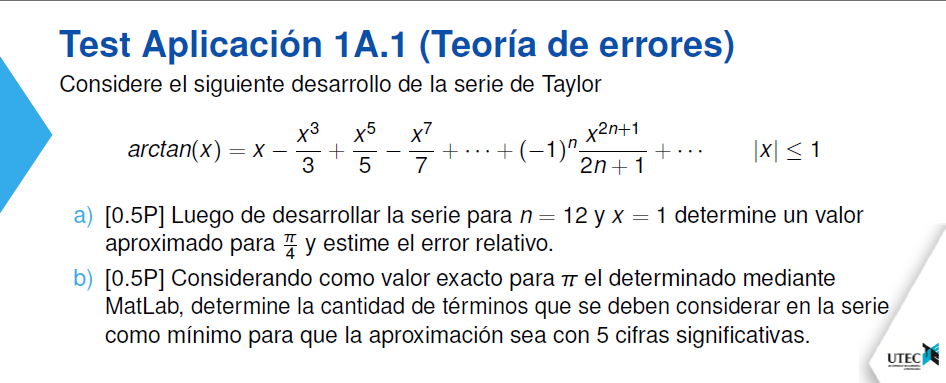

Item a)

format long

n = 12;
x = 1;

arctan_aprox = arctan_taylor_it(x, n);
arctan_exact = atan(x);

fprintf('La función arctan(x) aproximada para x = 1 y n = 12 es: %f', arctan_aprox);

La función arctan(x) aproximada para x = 1 y n = 12 es: 0.804601

fprintf('La función arctan(x) exacta para x = 1 es: %f', arctan_exact);

La función arctan(x) exacta para x = 1 es: 0.785398

x = pi/4;

arctan_aprox = arctan_taylor_it(x, n);
arctan_exacto = atan(x);
delta = abs(exacto - aprox)/abs(exacto);

fprintf('La función arctan(x) aproximada para x = pi/4 y n = 12 es: %f', arctan_aprox);

La función arctan(x) aproximada para x = pi/4 y n = 12 es: 0.665808

fprintf('El error relativo es: %f', delta);

El error relativo es: 0.000052

Item b) 

csig = 5;

terminos = arctan_taylor_nterm(x, csig);

fprintf('Nro de términos para aproximar arctan(x) es: %d', terminos);

Nro de términos para aproximar arctan(x) es: 15


% Comprobación
arctan_taylor_it(x, terminos);
atan(x);

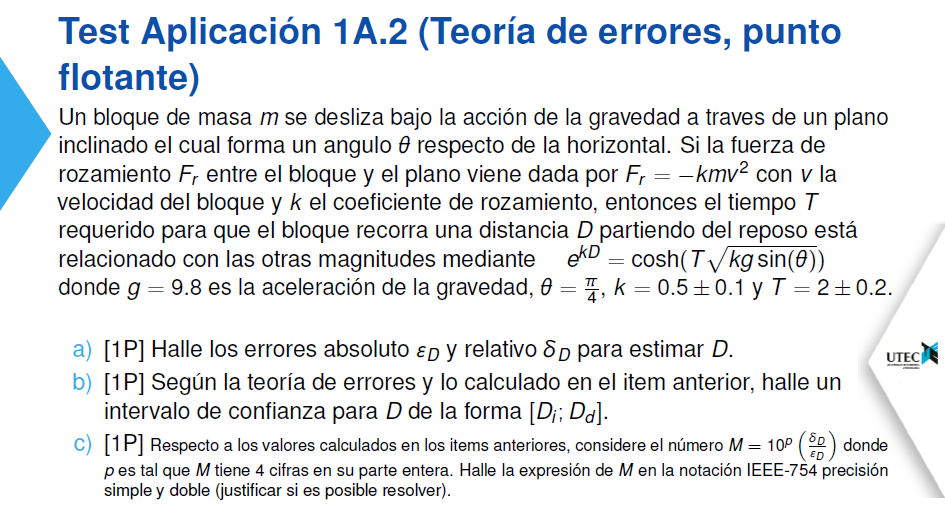

Item a)

g = 9.8; 
theta = pi/4;
k1 = 0.5; error_k = 0.1;
T1 = 2; error_T = 0.2;

syms T k
D = 1/k * log(cosh(T * sqrt(k * g * sin(theta))));
D = matlabFunction(D);

dD_T = matlabFunction(diff(D,T));
dD_k = matlabFunction(diff(D,k));

delta_D = abs(dD_T(T1,k1)) * error_k + abs(dD_k(T1,k1)) * error_T;

errorabs_D = delta_D * D(T1, k1);

fprintf('Error absoluto de la función D: %f', errorabs_D);

Error absoluto de la función D: 7.931097

fprintf('Error relativo de la función D: %f', delta_D);

Error relativo de la función D: 1.308657

Item b

intervalo_inferior = D(T1, k1) - errorabs_D;
intervalo_superior = D(T1, k1) + errorabs_D;

fprintf('Intervalo de confianza para D: [%f, %f]', intervalo_inferior, intervalo_superior)

Intervalo de confianza para D: [-1.870609, 13.991584]

Item c

% IEEE-754 precisión simple
syms p
M = 10^p * (delta_D/errorabs_D);
M = matlabFunction(M);

n = M(4);

dec2bin(n)

ans = '11001110010'


bin_simple = simple2binary(n);

fprintf("El número M es: %f", n);

El número M es: 1650.032266

fprintf("IEEE-754 simple: %s", bin_simple);

IEEE-754 simple: 0100010011001110010000010000100001010001


% IEEE-754 precisión doble
bin_doble = double2binary(n);

fprintf("IEEE-754 doble: %s", bin_doble);

IEEE-754 doble: 010000001001100111001000001000010000101000111101101101110011001

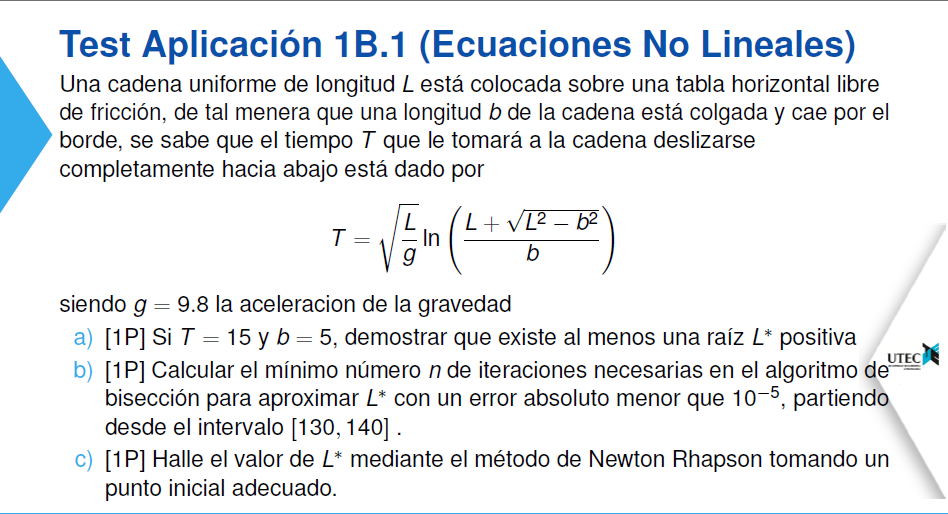

Angello

%Codes

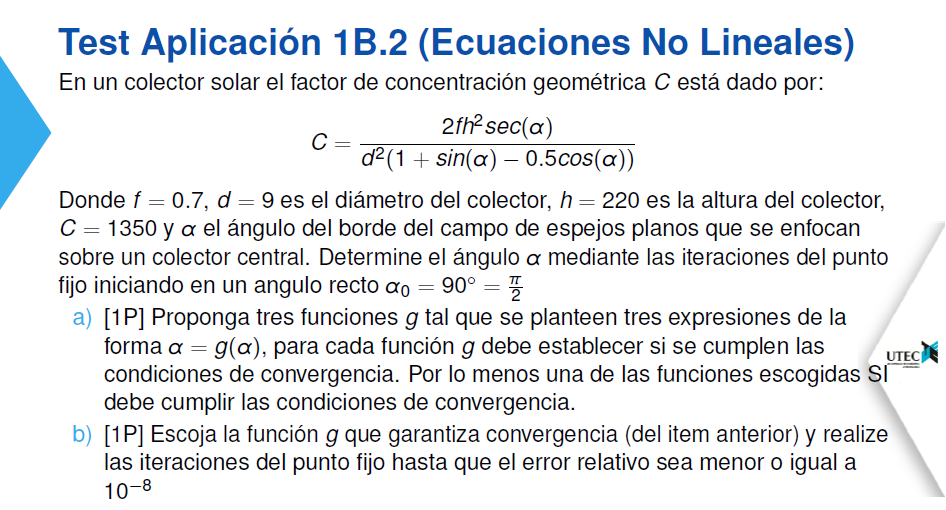

Angello

%codes

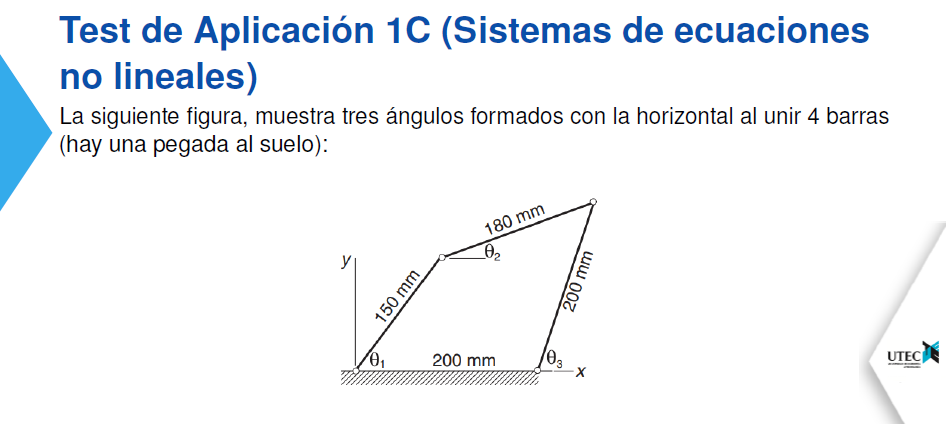

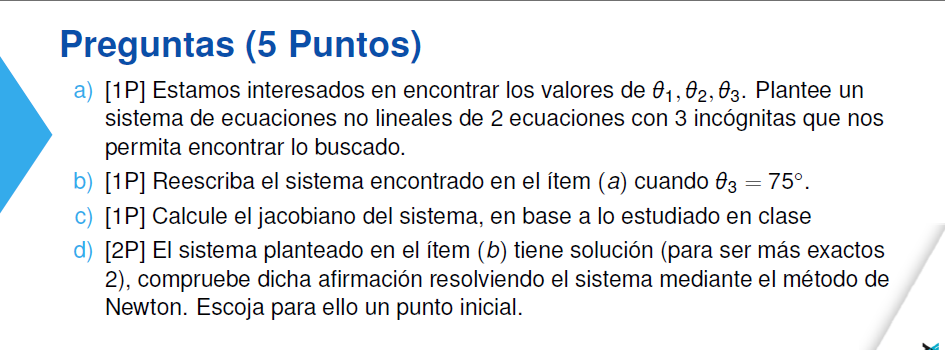

Jeffrey

%codes

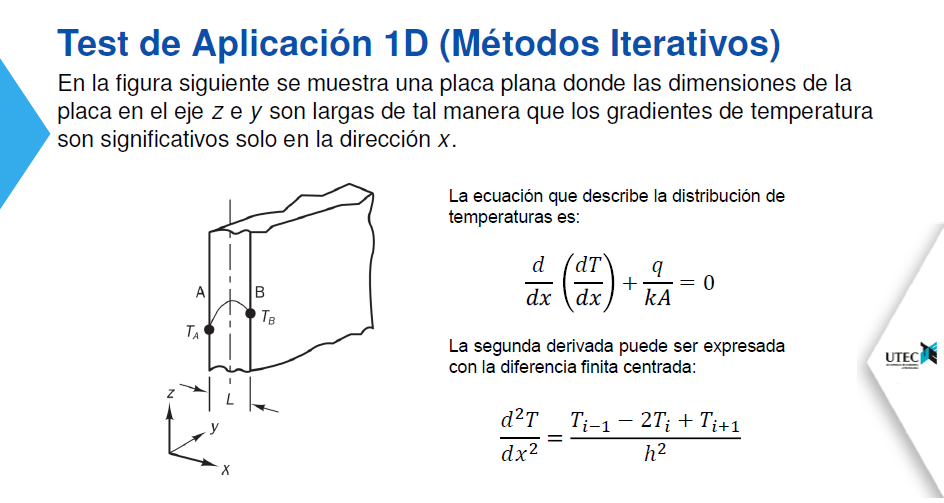

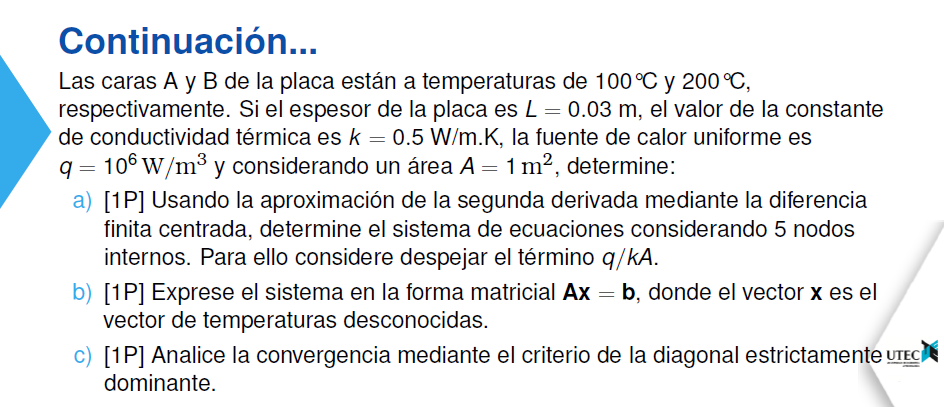

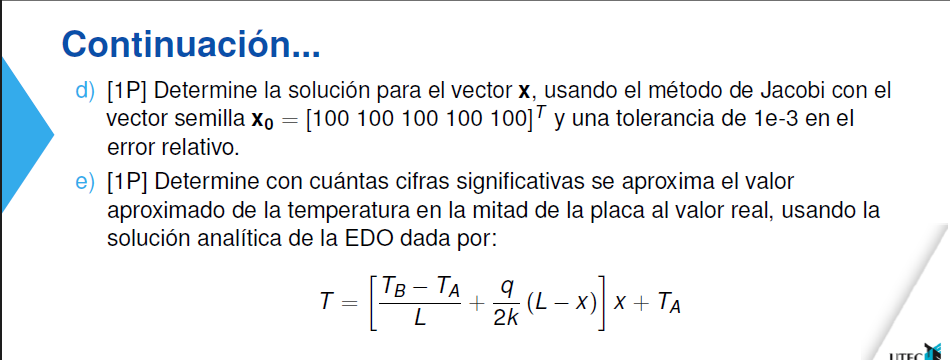

Angello

%codes

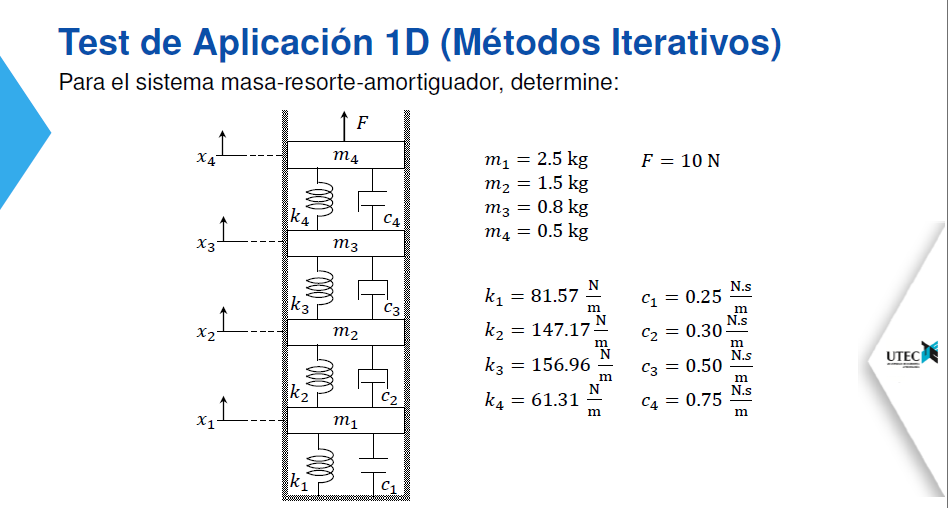

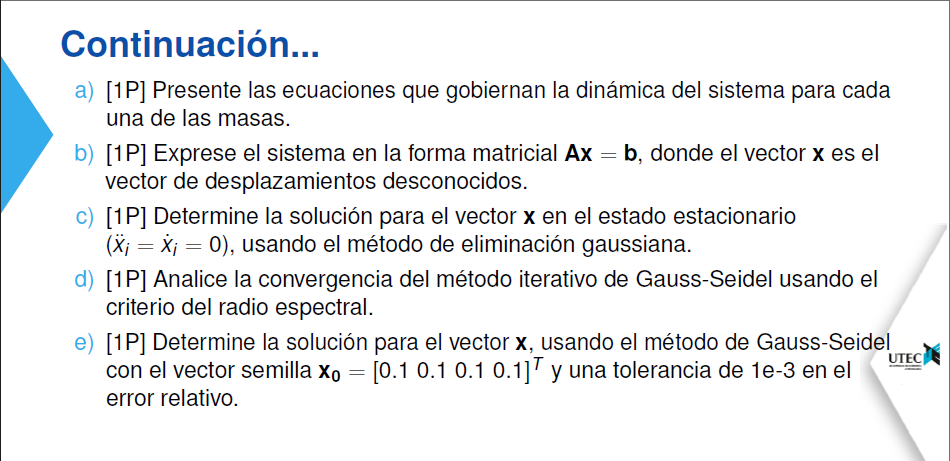

Juan Carlos

%codes

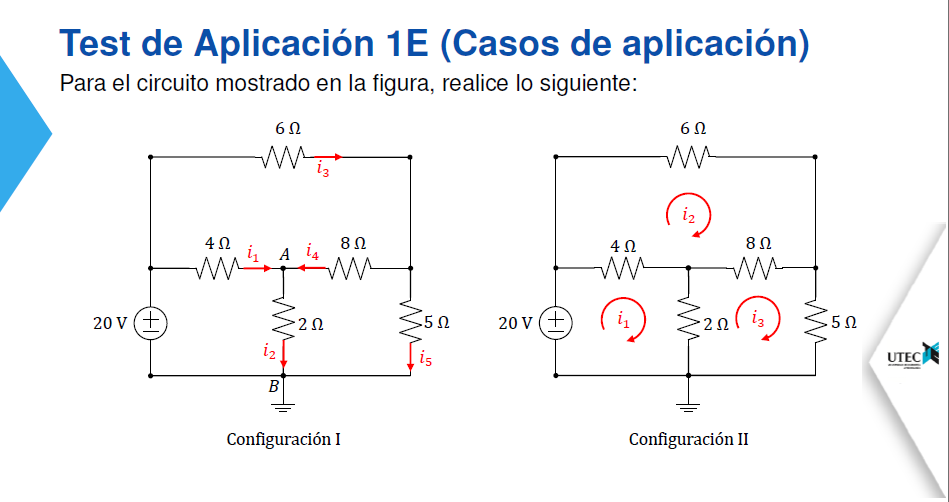

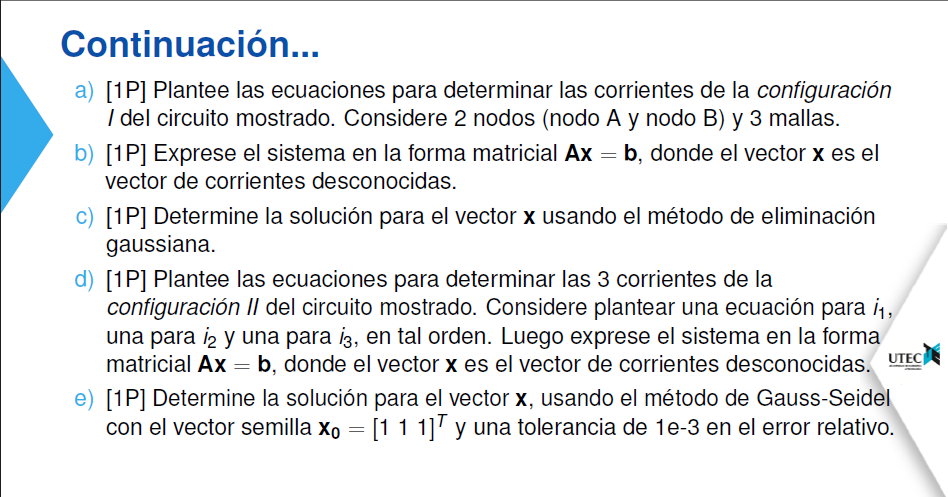

Juan Carlos

%codes


1A.1. Función arctan(x) con la aproximación de Taylor

function sol = arctan_taylor_it(x, n)
    sol = 0;

    for i = 0:n
        sol = sol + (-1)^i * (x^(2*i + 1))/(2*i + 1);
    end
end

1A.1. Función para hallar la cantidad de términos necesarios para ciertas cifras significativas

function sol = arctan_taylor_nterm(x, n)
    nterm = 0;
    anterior = arctan_taylor_it(x, nterm);
    delta = 1;

    while (delta > 5 * 10^-n)   
        nterm = nterm + 1;
        actual = arctan_taylor_it(x, nterm);
        delta = abs(actual - anterior)/abs(actual);
        anterior = actual;
    end

    sol = nterm + 1;
end

1A.2. Función para calcular binario IEEE-754 precisión simple

function x = simple2binary(n)
    % Signo
    if n < 0 
        sign = "1";
    else
        sign = "0";
    end

    % Extraer la parte entera
    entero = floor(n);

    bin_ent = num2str(dec2bin(entero));

    % Extraer la parte decimal    
    b = mod(n, 10);
    bin_dec = "";
    
    for i = 1: 32 - length(bin_ent)
        if b < 1
            b = b * 2;
        else
            b = b - 1;
            b = b * 2;
        end
   
        bin_dec = bin_dec + num2str(floor(b));
    end

    % Mantiza
    mantiza = bin_ent(2:end) + bin_dec;

    % Exponente
    exp = 127 + length(bin_ent(2:end));
    exp = num2str(dec2bin(exp));

    % Unión
    x = sign + exp + mantiza;
end

1A.2. Función para calcular binario IEEE-754 precisión doble

function x = double2binary(n)
    % Signo
    if n < 0 
        sign = "1";
    else
        sign = "0";
    end

    % Extraer la parte entera
    entero = floor(n);

    bin_ent = num2str(dec2bin(entero));

    % Extraer la parte decimal    
    b = mod(n, 10);
    bin_dec = "";
    
    for i = 1: 52 - length(bin_ent)
        if b < 1
            b = b * 2;
        else
            b = b - 1;
            b = b * 2;
        end
   
        bin_dec = bin_dec + num2str(floor(b));
    end

    % Mantiza
    mantiza = bin_ent(2:end) + bin_dec;

    % Exponente
    exp = 1023 + length(bin_ent(2:end));
    exp = num2str(dec2bin(exp));

    % Unión
    x = sign + exp + mantiza;
end